g  = 9.81;
l  = 0.5;
l_a= 0.3;
m  = 5;

## sampling frekansları farklı olduğu için istediğimiz verileri çekelim

w = (-1)*knee.GYROXdegs(1:4967)*pi/180;
a_n = (-1)*knee.ACCYG(1:4967)*g;
a_t = knee.ACCZG(1:4967)*g;

**herhangi bir time series(emg hariç)**

tseri = knee.ACCXTimeSeriess(1:4967);
tstep = 0.00675;

**BİASLERİ ÇIKARALIM**

% ilk 1 saniyede çıkar
w = w - mean(w(1:150));
a_n = a_n - mean(a_n(1:150));
a_t = a_t - mean(a_t(1:150));

**TETA ve ALFAYI TANIMLAYALIM**

temp = (w.^2*l_a - a_n)/g

temp =    -0.0006
   -0.0022
    0.0003
    0.0003
   -0.0041
   -0.0034
   -0.0072
   -0.0047
   -0.0039
   -0.0043


ans =         1503
        1504
        1505
        1506
        1517
        1518
        1519
        1520
        1525
        1526


temp(temp>1)=1

temp =    -0.0006
   -0.0022
    0.0003
    0.0003
   -0.0041
   -0.0034
   -0.0072
   -0.0047
   -0.0039
   -0.0043


temp(temp<-1)=-1

temp =    -0.0006
   -0.0022
    0.0003
    0.0003
   -0.0041
   -0.0034
   -0.0072
   -0.0047
   -0.0039
   -0.0043


%tetayı omeganın integralini alarak hesapla
%1D kalman filtresi bak, teta 0dan başlamak zorunda

teta = acos(temp);
alfa = (a_t + g*sin(teta))/l_a;
(w.^2*l_a - a_n)/g

ans =    -0.0006
   -0.0022
    0.0003
    0.0003
   -0.0041
   -0.0034
   -0.0072
   -0.0047
   -0.0039
   -0.0043


**KONTROL EDELİM**

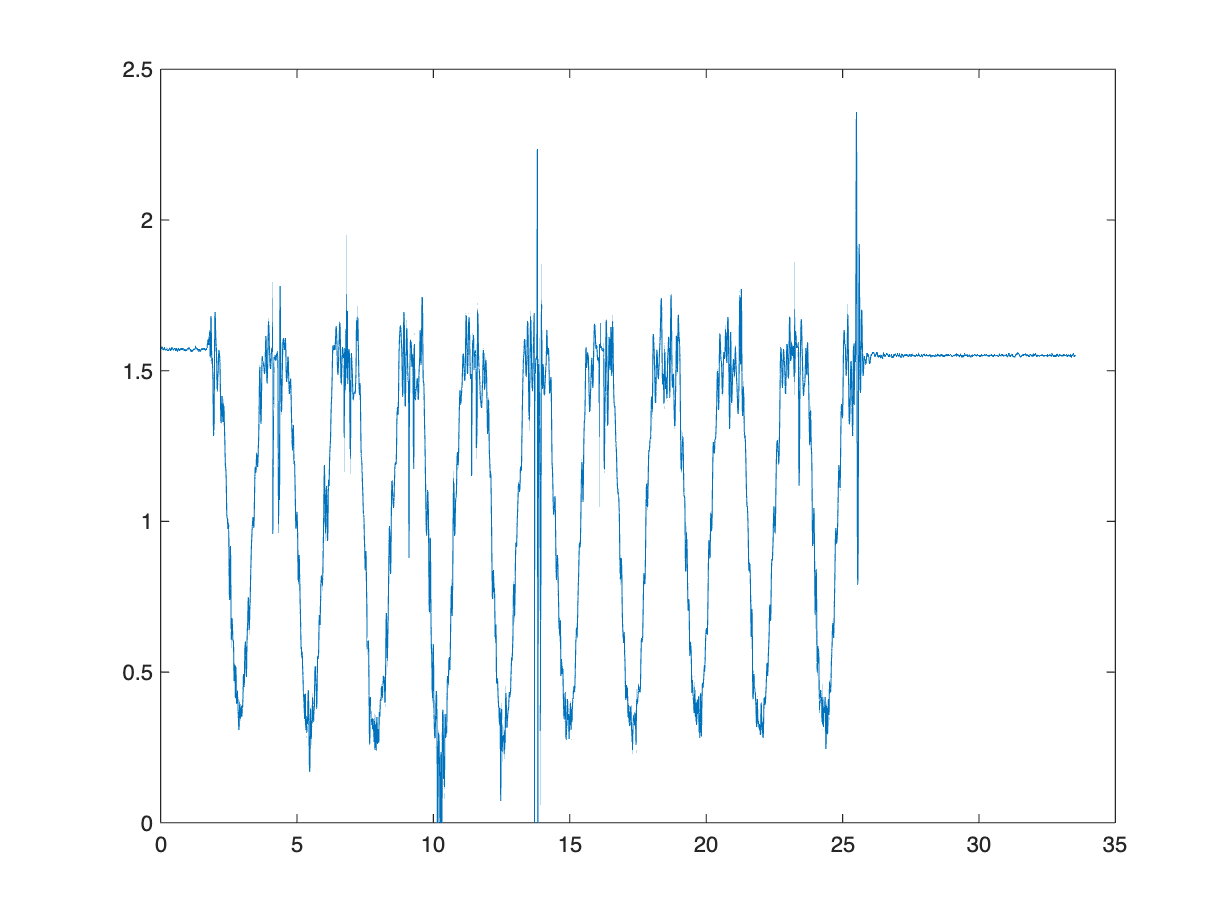

plot(tseri, teta) 

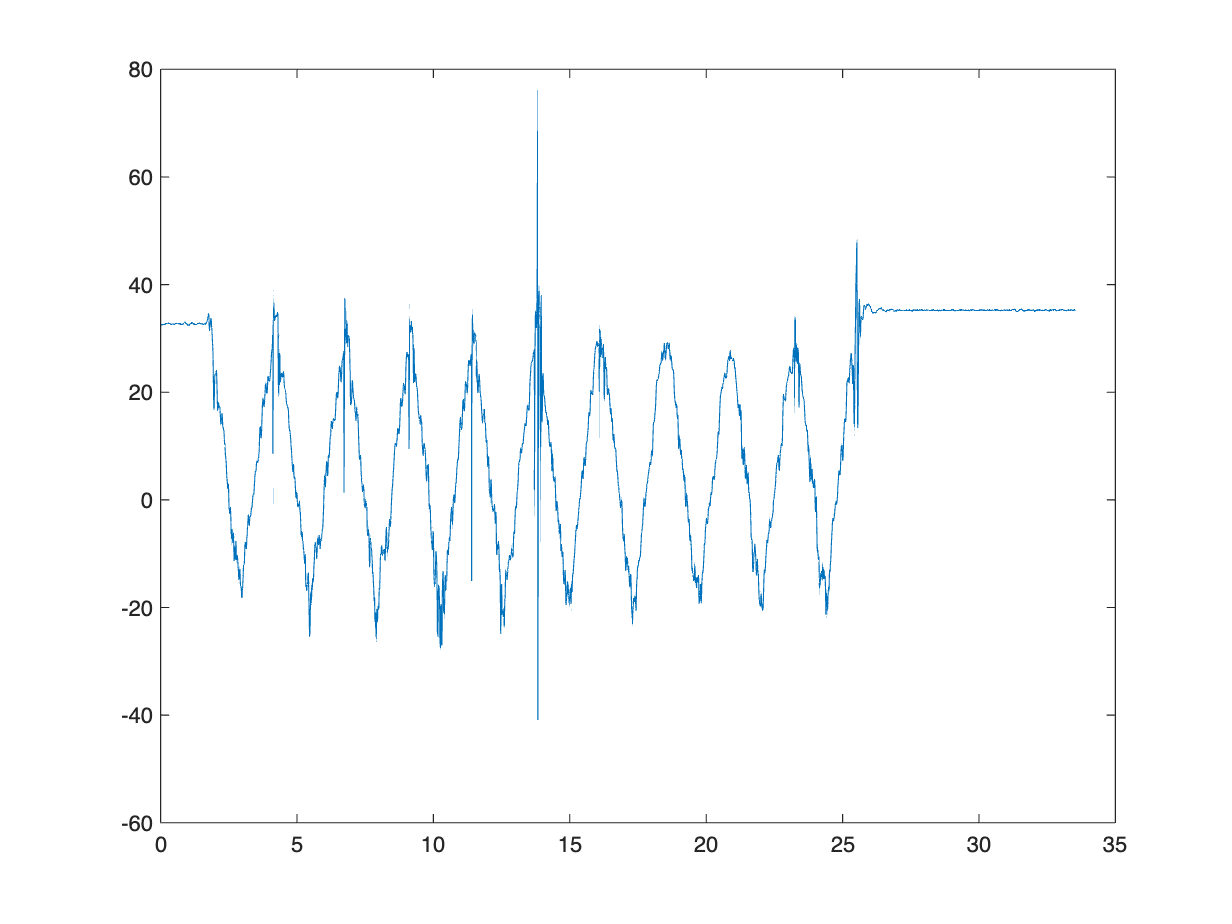

plot(tseri, alfa)

**DEĞERLER TUTARLI MI KONTROL EDELİM**

A_n = w.^2*l_a - g*cos(teta); %formulde yerine yazıyoruz
A_t = alfa*l_a - g*sin(teta);

error_1 = abs(mean((A_n - a_n).^2))

error_1 = 0.0212

error_2 = abs(mean((A_t - a_t).^2))

error_2 = 3.5005e-31

**alfa tetanın ikinci türevine karşılık geliyor mu? ne kadar geliyor?**

% diff fonskiyonu dene
%integralleri dene

for i = 2:1:4966
    teta_turev1(i) = (teta(i+1)-teta(i-1)) / (2*tstep);
end

% omegayı dene

for i = 2:1:4965
    teta_turev2(i) = (teta_turev1(i+1)-teta_turev1(i-1)) / (2*tstep);
end

teta_turev2.';

mse = abs(mean( (teta_turev2(3:end).' - alfa(3:4965)).^2 )) % error çok büyük

mse = 3.9192e+05

**MATEMATİKSEL MODELİ KULLANARAK BİR ŞEYLER DENEYELİM**

tork_o = (m * l^2/3) .* alfa + (m*g*l/2) .* sin(teta)

tork_o =    25.8514
   25.8813
   25.8531
   25.8356
   25.8080
   25.7981
   25.8084
   25.7929
   25.8113
   25.8670


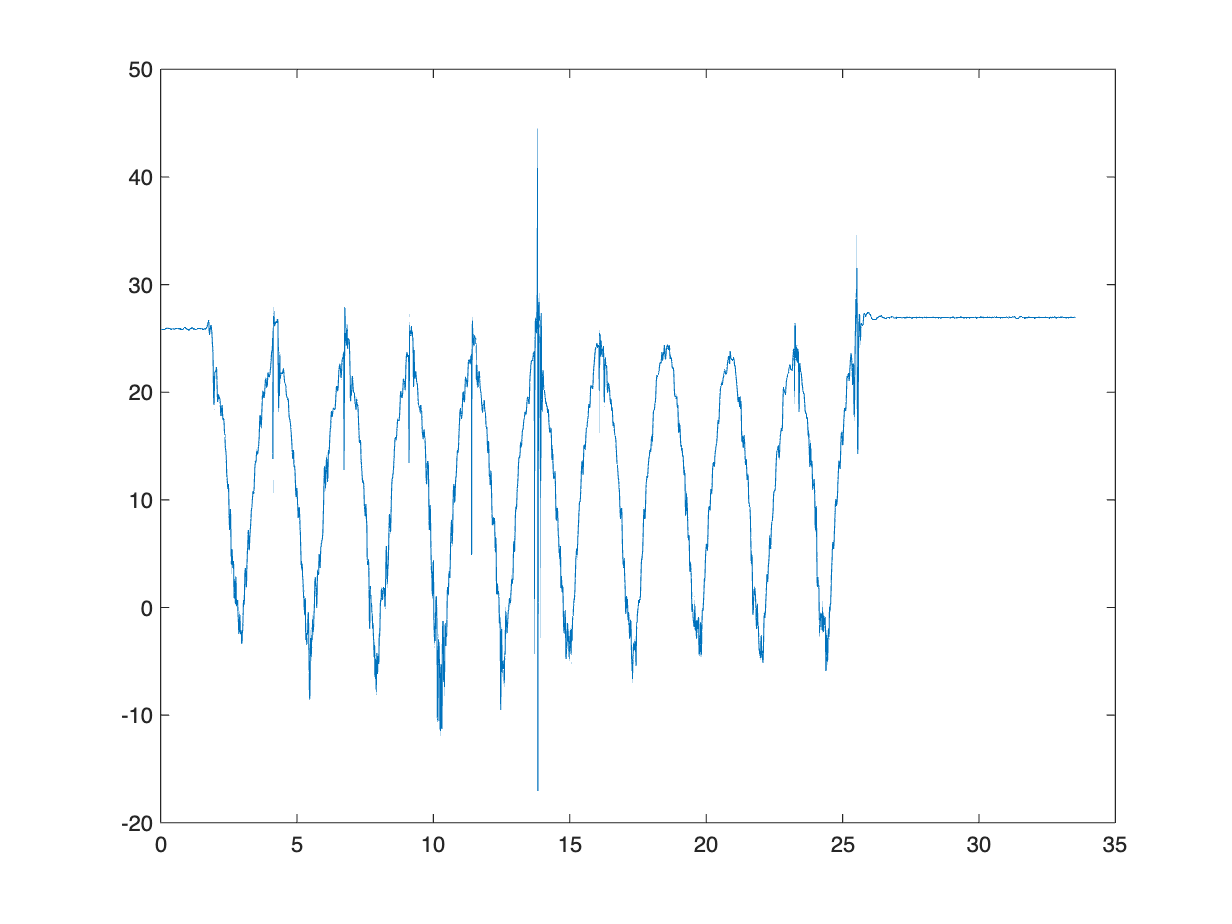


plot(tseri, tork_o)

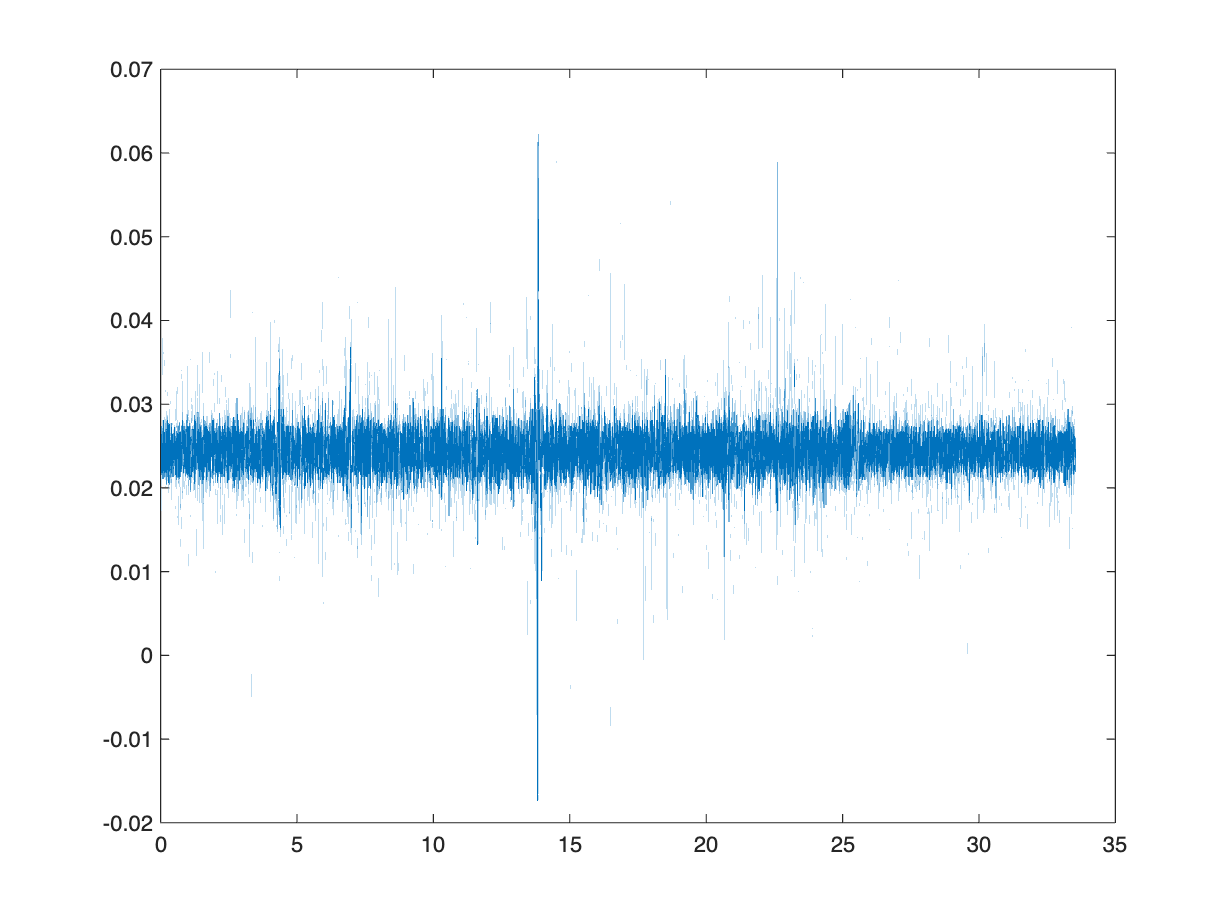


tseri2 = knee.EMG1TimeSeriess;
plot(tseri2, knee.EMG1mV);

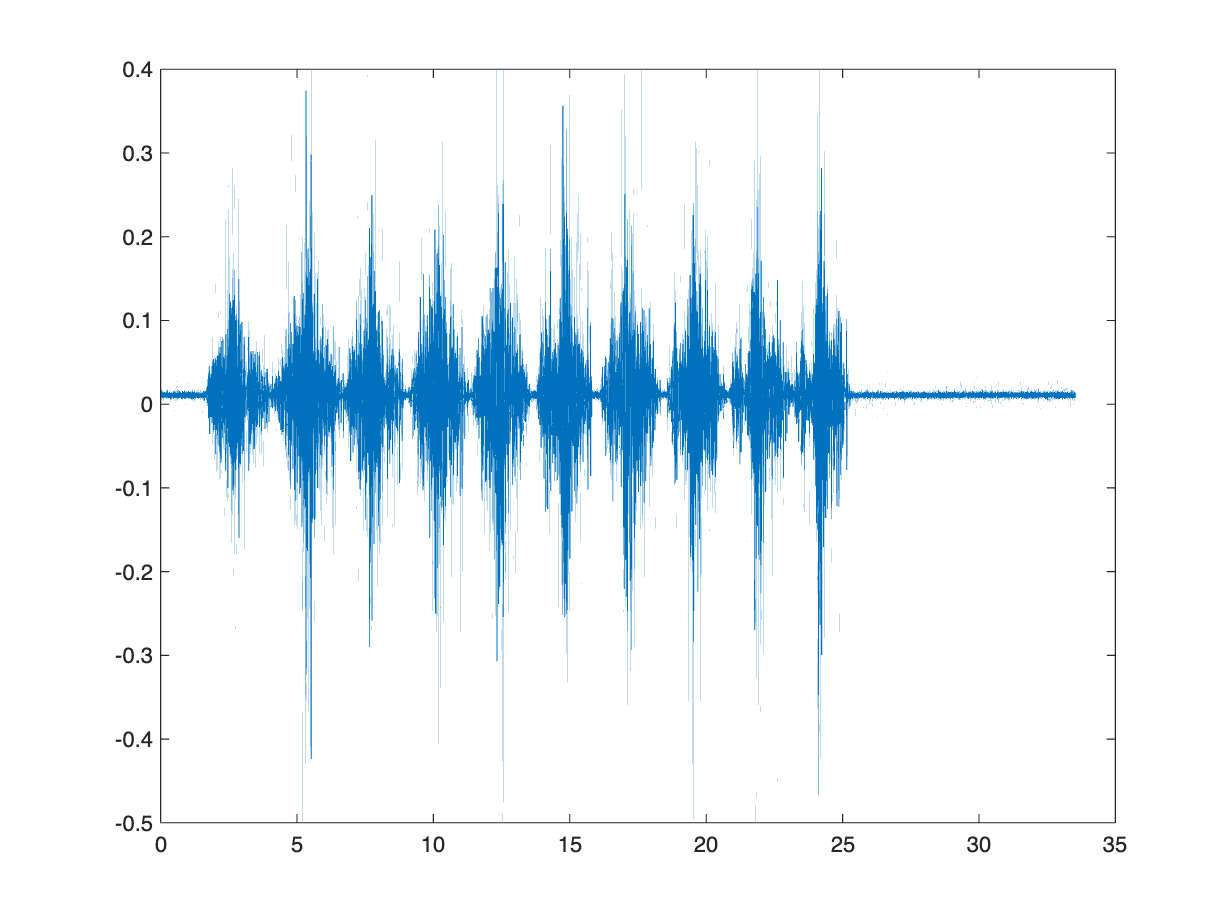

plot(tseri2, knee.EMG1mV1);

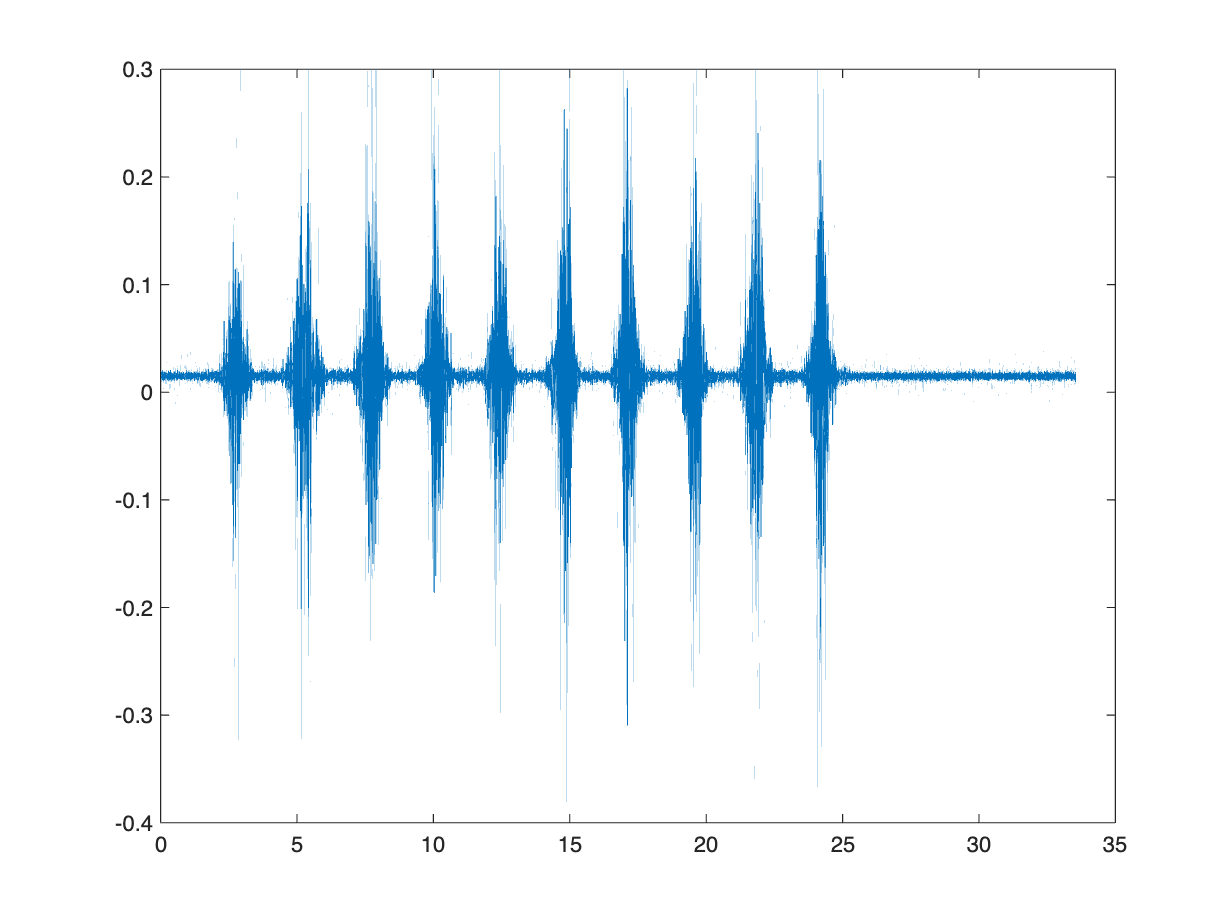

plot(tseri2, knee.EMG1mV2);